# Receiver Operating Characteristic (ROC)

In this demonstration, we will look at the ROC curves of a few different detection statistics for the DC signal in White Gaussian Noise (WGN) example. 

For this example, we have the following binary hypotheses:

- 
$$H_{0\;} :\bar{y} =\bar{n}$$


- 
$$H_{1\;} :\bar{y} =\bar{s} +\bar{\;n}$$


where, for $i=0,1,\ldots,N-1$, $s_i =\mu \not= 0$, is a constant, and the WGN has zero mean and unit variance.

We will consider the following detection statistics:

- Likelihood Ratio: $\Gamma_1 =\frac{1}{N}\sum_{i=0}^{N-1} y_i$ (see lecture slides for the derivation)

- Sample median: $\Gamma_2 =$ middle sample in the sorted $\bar{y}$ vector

- Center of range: $\Gamma_3 =\frac{1}{2}\left(\min \left(\bar{y} \right)+\max \left(\bar{y} \right)\right)$

One can code the simple detection statistics above efficiently using function handles. More complicated detection statistics will require the corresponding functions to be defined in a separate file. The function handles can be stored in a cell array for easy retrieval in a loop.

For the WUN case this is a little bit different, but uses an existing statistic. See pdf for derivation. 

nStats = 3; %Number of detection statistics
gamma1 = @(x) mean(x);
gamma2 = @(x) median(x);
gamma3 = @(x) (min(x)+max(x))/2; % this is the LR statistic best suited to WGN
gammaArr = {gamma1,gamma2,gamma3};

The ROC curves are obtained using simulated data realizations under the two hypotheses. The number of data realizations and the number of samples $N$ are set below. The basic idea is to get trial values of $\Gamma_i$ from data realizations under the two hypotheses and estimate the corresponding pdf's, $p_{\Gamma_i}(x|H_0)$ and $p_{\Gamma_i}(x|H_1)$, from the set of trial values. 

nSmpls = 100;%Number of samples 
nRlz = 10000; %Number of realizations

The DC signal value is set below. 

mu = 0.1;

A **simulated** data realization under $H_0$, i.e., a noise realization, is obtained using `rand `and the constant `mu` is added to the same noise realization to obtain a data realization under $H_1$. (In principle, one could also generate the realizations independently for the two hypotheses but that just takes longer.) Here, for each data realization, the detection statistic values are computed and stored in pairs of rows in a single matrix.

gammaVals = zeros(2*nStats, nRlz);
%To allow reproducibility, we will initialize the random
%number generator
rng('default');
for lrz = 1:nRlz
    nVec = unifrnd(-0.5, 0.5, 1, nSmpls);
    yVec = nVec + mu;
    %Loop over the detection statistics and 
    %compute values for H_0 and H_1
    for lstat = 1:nStats
        h0Val = gammaArr{lstat}(nVec);
        h1Val = gammaArr{lstat}(yVec);
        %Store the values in two rows
        gammaVals(2*lstat-1,lrz) = h0Val;
        gammaVals(2*lstat,lrz) = h1Val;
    end
end

We can plot the estimated pdf for each statistic under each hypothesis.

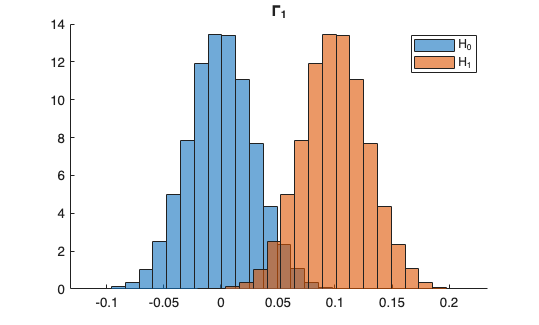

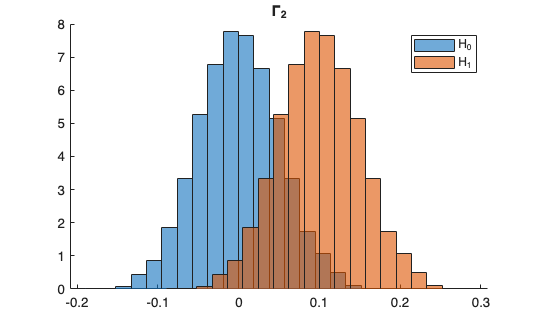

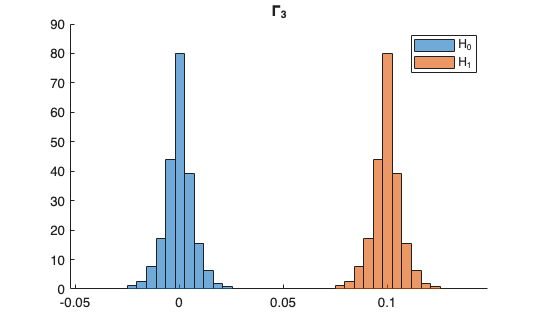

for lstat = 1:nStats
    figure;
    hold on;
    h0GmaVec = gammaVals(2*lstat-1,:);
    h1GmaVec = gammaVals(2*lstat,:);
    histogram(h0GmaVec,20,"Normalization","pdf");
    histogram(h1GmaVec,20,"Normalization","pdf");
    legend("H_0","H_1");
    title(['\Gamma_',num2str(lstat)]);
    drawnow;
end

Now, we estimate the detection and false alarm probabilities for each detection statistic as functions of the detection threshold. 

A clever way to do this is to use the trial values of the detection statistic under $H_0$ themselves as the detection thresholds. For this, we simply sort the trial values under $H_0$ in ascending order. Then, for an element $\Gamma_i[k]$ with index $k$ in the **sorted** array, the probability of crossing the threshold is simply given by $\frac{M-k}{M}$, where $M$is the number of trial values. Thus, we actually do not need to do any calculation for the false alarm probability! 

However, for the detection probability, we need the sorted values: For each $\Gamma_i[k]$ above, we have to count how many trials values under $H_1$ exceed $\Gamma_i[k]$. Normally, one would need to search for the values that exceed the threshold but this can also be achieved efficiently:  subtract $\Gamma_i[k]$ from the trial values under $H_1$, get the signs of the resulting values, add 1, divide by 2, and sum all the values. The idea here is that values exceeding $\Gamma_i[k]$ will have a positive sign and those that do not will have a negative sign. Adding 1 will turn all -1's to zeroes and +1's to 2. Dividing by 2 will leave behing only +1's, which can be added up to get the required count. Doing things algebraically is much more efficient than using a search. (Note that we did not address the case of getting a zero value after subtraction. However, the probability of getting an exact zero is vanishingly small.)

Q_d = zeros(nStats,nRlz);
%Under our scheme, false alarm probabilities do not need the trial values 
Q_0 = (nRlz - (1:nRlz))/nRlz;
for lstat = 1:nStats
    h0Val = gammaVals(2*lstat-1,:);
    h1Val = gammaVals(2*lstat,:);
    h0Val = sort(h0Val,'ascend');
    h1Val = sort(h1Val,'ascend');
    %Subtract the threshold and sum up the 
    %signs of the results to get the number of 
    %trials values exceeding the threshold
    for lrz = 1:nRlz
        Q_d(lstat,lrz) = sum ((sign(h1Val-h0Val(lrz))+1)/2)/nRlz;
    end
end

Now, we can plot the ROC.

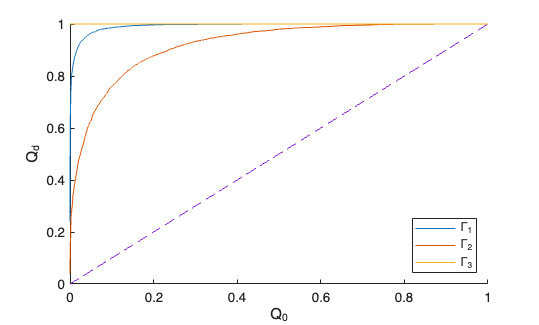

figure;
hold on;
lgndStr = cell(1,nStats);%Cell array for legends
for lstat = 1:nStats
    plot(Q_0, Q_d(lstat,:));
    lgndStr{lstat} = ['\Gamma_',num2str(lstat)];
end
%Also plot the diagonal
plot([0,1],[0,1],'--');
xlabel('Q_0');
ylabel('Q_d');
legend(lgndStr,'Location','southeast');